6. Programmatically plot 50 circles in 3D with radii ranging from 1 to 100 with increments of 2, and the z-axis separation of 1. 

radii = 1:2:100

radii =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99


height = 1:numel(radii)

height =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


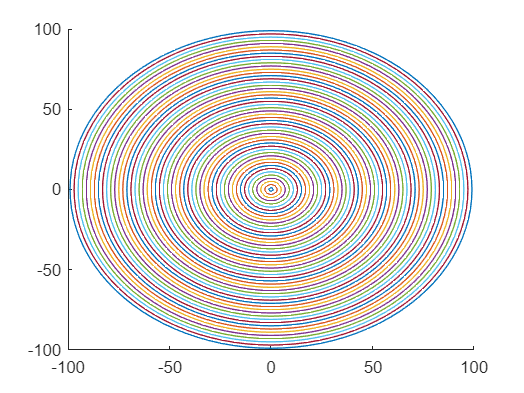


%function to graph circle
figure 
circle3D(radii,height); %to do output graph as 3D

7. Assume a sampling rate of 1000 samples/s, create a new figure, split it into 4 separate plots (2x2), scale and optimize each plot as you see fit after you

a. Plot the unit step function in continuous time and discrete time 

b. Plot the unit impulse function in continuous time and discrete time 

c. Plot the standard ramp function in continuous time and discrete time 

d. Plot a square wave in continuous time and discrete time

t_min = -1;
t_max = 1;
t_size = abs(t_min) + abs(t_max);
sample_rate = 1000*t_size %one sample every 0.001s

sample_rate = 2000

t = linspace(t_min,t_max,sample_rate)

t =    -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


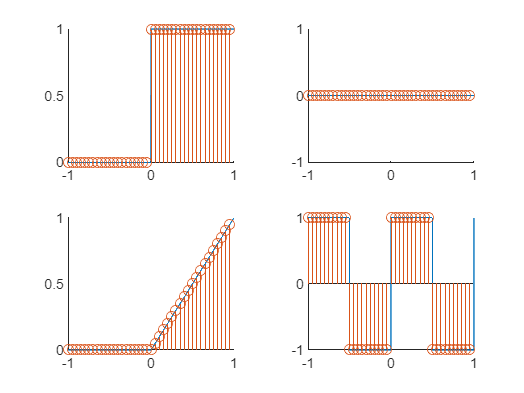


ds_factor = 50; %downsampling dactor

%declare functions
unitstep = t>=0;
impulse = t==0;
ramp = t.*unitstep;
%quad = t.^2.*unitstep;
sqwave = square(2*pi*t);

figure
tiledlayout(2,2)
nexttile
plot_signal(t, unitstep, ds_factor)
nexttile
plot_signal(t, impulse, ds_factor)
nexttile
plot_signal(t, ramp, ds_factor)
nexttile
plot_signal(t, sqwave, ds_factor)

t_down = downsample(t,50);
sqwave_down = downsample(sqwave,50);

figure
hold on
plot(t, sqwave)
% %plot(downsample(t,100), stem(downsample(sqwave,100)))
stem(t_down, sqwave_down)

figure
hold on
plot(t, unitstep)
stem(downsample(t,50), downsample(unitstep,50))

Functions for assignment

function circle3D(r,z)
    hold on
    for i = 1:numel(r)
        th = 0:pi/50:2*pi;
        x = r(i) * cos(th);
        y = r(i) * sin(th);
        h = plot3(x, y, zeros(1,numel(x))+z(i));
    end
    hold off
end

function plot_signal(time,signal,ds_factor)
    %downsample signal
    time_down = downsample(time,ds_factor);
    signal_down = downsample(signal,ds_factor);
    
    %plot continuous and discrete functions
    hold on
    plot(time, signal)
    stem(time_down, signal_down)
    hold off
end